## **Name: Md Toufique Hasan**

## **Student Number: 151129267**

## **Exercise date: 17/11/2022**

## **Data Mining Exercise: 2**

### ***Answer 1***

%% Read File
file = readtable('D:\TUNI\Courses\Period-2\DATA.ML.340 [Data Mining]\Weekly exercises 1\inco13par.txt')

file = 529×16 table
    NO    DIAGNOSI    UVA    US     PVR    PMU     CYM    PTR    MUC    SS     UVJ    SSY    CLU    DV    USY    AGE
    __    ________    ___    ___    ___    ____    ___    ___    ___    ___    ___    ___    ___    __    ___    ___

     2       0         0       8      1    0.05      0     68      0      0      1     1      0     0      1     62 
     3       0         0       4     30     0.2      0     72     -9      0    NaN  

This **inco13par.txt **file has 529 Rows and 16 Columns. 

**NO** is an Index Variable and no statistic can be calculated.

**DIAGNOSI** is Nominal variable and MODE can be calculated.

**UVA** is Binary variable and MODE can be calculated.

**US** is Nominal Variable and MODE can be calculated.

**PVR** is Nominal Variable and MODE can be calculated.

**PMU** is Nominal Variable and MODE can be calculated.

**CYM** is Nominal Variable and MODE can be calculated.

**PTR** is Nominal Variable and MODE can be calculated.

**MUC** is Nominal Variable and MODE can be calculated.

**SS** is Binary Variable and MODE can be calculated.

**UVJ** is Nominal Variable and MODE can be calculated.

**SSY** is Nominal Variable and MODE can be calculated.

**CLU** is Binary Variable and MODE can be calculated.

**DV** is Binary Variable and MODE can be calculated.

**USY** is Binary Variable and MODE can be calculated.

**Age** is Continuous Variable and MODE/MEDIAN can be calculated.

%% Different Diagnoses
unique(file.DIAGNOSI)

ans =      0
     1
     2
     3
     4


Here, 0 means no diseases and 1-4 means different types of diseases.

%% Mean Age
meanAge = mean(file.AGE, 'omitnan')

meanAge = 52.3276

### ***Answer 2***

%% Replace all missing variable values (NaN) using respective mean

Diagnosis0 = file(file.DIAGNOSI == 0, :)
Diagnosis1 = file(file.DIAGNOSI == 1, :)
Diagnosis2 = file(file.DIAGNOSI == 2, :)
Diagnosis3 = file(file.DIAGNOSI == 3, :)
Diagnosis4 = file(file.DIAGNOSI == 4, :)

row_column = size(file)
for n = 2:row_column(2)
Diagnosis0{:,n}(isnan(Diagnosis0{:,n}))= mean(Diagnosis0{:,n}, 'omitnan')
Diagnosis1{:,n}(isnan(Diagnosis1{:,n}))= mean(Diagnosis1{:,n}, 'omitnan')
Diagnosis2{:,n}(isnan(Diagnosis2{:,n}))= mean(Diagnosis2{:,n}, 'omitnan')
Diagnosis3{:,n}(isnan(Diagnosis3{:,n}))= mean(Diagnosis3{:,n}, 'omitnan')
Diagnosis4{:,n}(isnan(Diagnosis4{:,n}))= mean(Diagnosis4{:,n}, 'omitnan')
end

The output of Answer 2 is long, for this reason I do not show these here.

### ***Answer 3***

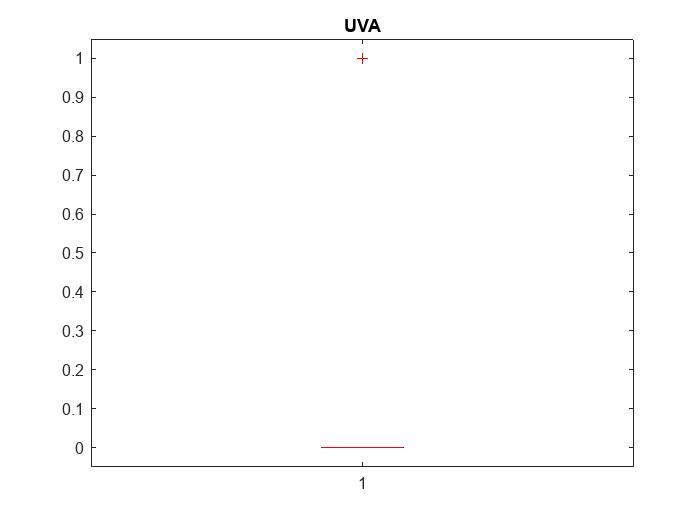

boxplot(file.UVA)
title('UVA')

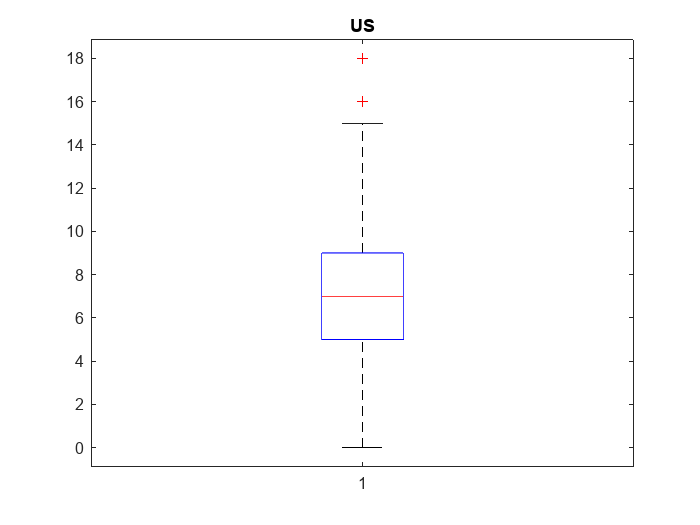

boxplot(file.US)
title('US')

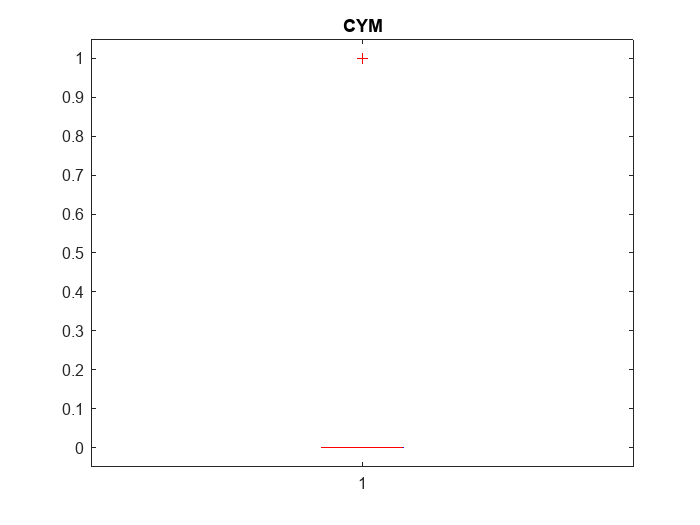

boxplot(file.UVA)
title('CYM')

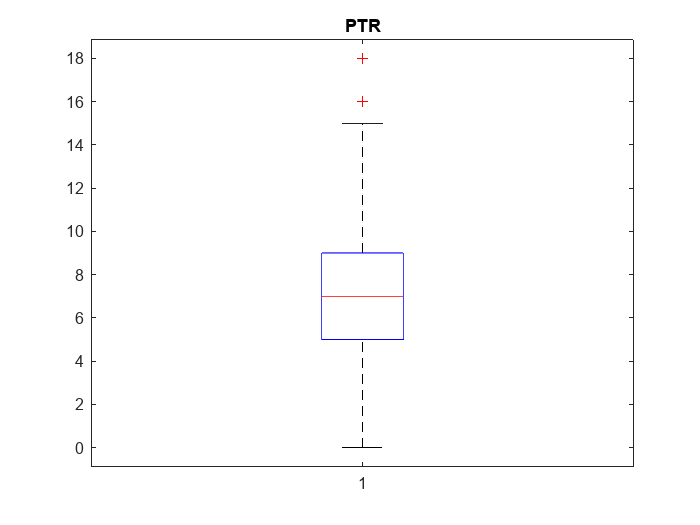

boxplot(file.US)
title('PTR')

**UVA** is binary variable.

**US** is Nominal variable.

**CYM** is binary variable.

**PTR** is Nominal variable.

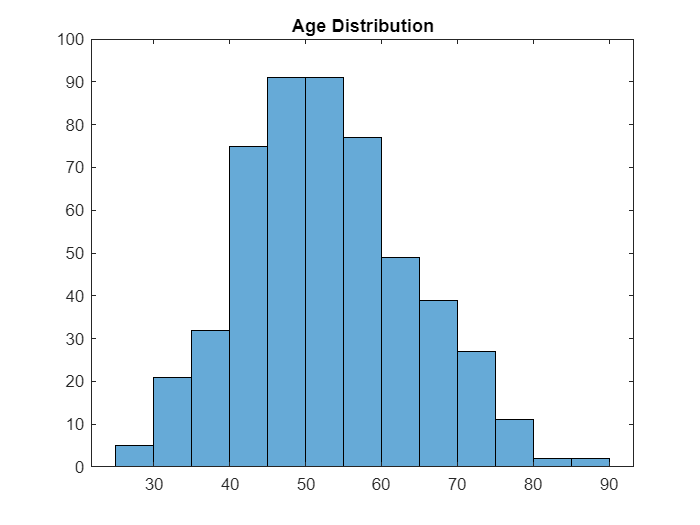

histogram(file.AGE)
title('Age Distribution')

From the above Histogram of Age Distribution, the values are in uniform form and these are discrete values. So I can say that this is similar to the Normal Distribution of the data.

### ***Answer 4***

%% Euclidean distances
row_2 = inco13par(2,:)

row_2 = 1×16 table
    NO    DIAGNOSI    UVA    US    PVR    PMU    CYM    PTR    MUC    SS    UVJ    SSY    CLU    DV    USY    AGE
    __    ________    ___    __    ___    ___    ___    ___    ___    __    ___    ___    ___    __    ___    ___

    3        0         0     4     30     0.2     0     72     -9     0     NaN     1      0     0      0     46 


row_269 = inco13par(269,:)

row_269 = 1×16 table
    NO     DIAGNOSI    UVA    US     PVR    PMU    CYM    PTR    MUC    SS    UVJ    SSY    CLU    DV    USY    AGE
    ___    ________    ___    ___    ___    ___    ___    ___    ___    __    ___    ___    ___    __    ___    ___

    458       0         0     NaN     1     0.4     0     64     -2     1      1      1      0     0      0     38 


row_393 = inco13par(393,:)

row_393 = 1×16 table
    NO     DIAGNOSI    UVA    US     PVR    PMU     CYM    PTR    MUC    SS    UVJ    SSY    CLU    DV    USY    AGE
    ___    ________    ___    ___    ___    ____    ___    ___    ___    __    ___    ___    ___    __    ___    ___

    469       1         0     NaN    20     0.95     0     68     -12    0      0      1      0     0      1     44 


%% Calculating Distance
distance_2_269 = sqrt(sum(table2array(row_2)-table2array(row_269)).^2)

distance_2_269 = NaN

distance_2_393 = sqrt(sum(table2array(row_2)-table2array(row_393)).^2)

distance_2_393 = NaN

distance_269_393 = sqrt(sum(table2array(row_269)-table2array(row_393)).^2)

distance_269_393 = NaN

269 and 393 are closest to each other.

I am using Euclidean Distance Measure with Nominal variables. Fot this reason the output is not coming. It is possible if the variable is Binary.  

There are plenty of others approaches. Such as: Hamming Distance, Manhattan Distance, Chebyshev Distance, Minkowski Distance etc.

### ***Answer 5***

%% Load File
fileCSV = TetuanCitypowerconsumptionNumeric

fileCSV = 1.0e+04 *

    0.0001    0.0007    0.0074    0.0000    0.0000    0.0000    3.4056    1.6129    2.0241
    0.0001    0.0006    0.0075    0.0000    0.0000    0.0000    2.9815    1.9375    2.0131
    0.0001    0.0006    0.0075    0.0000    0.0000    0.0000    2.9128    1.9007    1.9668
    0.0001    0.0006    0.0075    0.0000    0.0000    0.0000    2.8229    1.8361    1.8899
    0.0001    0.0006    0.0076    0.0000    0.0000    0.0000    2.7336    1.7872    1.8442
    0.0001    0.0006    0.0077    0.0000    0.0000    0.0000    2.6625    1.7416    1.8130
    0.0001    0.0006    0.0078    0.0000    0.0000    0.0000    2.5999    1.6993    1.7945
    0.0001    0.0005    0.0078    0.0000    0.0000    0.0000    2.5446    1.6661    1.7459
    0.0001    0.0006    0.0078    0.0000    0.0000    0.0000    2.4778    1.6227    1.7026
    0.0001    0.0005    0.0077    0.0000    0.0000    0.0000    2.4279    1.5939    1.6794


%% Remove the first row (variable names)
fileCSV(1,:) = []

fileCSV = 1.0e+04 *

    0.0001    0.0006    0.0075    0.0000    0.0000    0.0000    2.9815    1.9375    2.0131
    0.0001    0.0006    0.0075    0.0000    0.0000    0.0000    2.9128    1.9007    1.9668
    0.0001    0.0006    0.0075    0.0000    0.0000    0.0000    2.8229    1.8361    1.8899
    0.0001    0.0006    0.0076    0.0000    0.0000    0.0000    2.7336    1.7872    1.8442
    0.0001    0.0006    0.0077    0.0000    0.0000    0.0000    2.6625    1.7416    1.8130
    0.0001    0.0006    0.0078    0.0000    0.0000    0.0000    2.5999    1.6993    1.7945
    0.0001    0.0005    0.0078    0.0000    0.0000    0.0000    2.5446    1.6661    1.7459
    0.0001    0.0006    0.0078    0.0000    0.0000    0.0000    2.4778    1.6227    1.7026
    0.0001    0.0005    0.0077    0.0000    0.0000    0.0000    2.4279    1.5939    1.6794
    0.0001    0.0006    0.0077    0.0000    0.0000    0.0000    2.3897    1.5436    1.6638


%% Remove the first column (date info)
fileCSV(:,1) = []

fileCSV = 1.0e+04 *

    0.0006    0.0075    0.0000    0.0000    0.0000    2.9815    1.9375    2.0131
    0.0006    0.0075    0.0000    0.0000    0.0000    2.9128    1.9007    1.9668
    0.0006    0.0075    0.0000    0.0000    0.0000    2.8229    1.8361    1.8899
    0.0006    0.0076    0.0000    0.0000    0.0000    2.7336    1.7872    1.8442
    0.0006    0.0077    0.0000    0.0000    0.0000    2.6625    1.7416    1.8130
    0.0006    0.0078    0.0000    0.0000    0.0000    2.5999    1.6993    1.7945
    0.0005    0.0078    0.0000    0.0000    0.0000    2.5446    1.6661    1.7459
    0.0006    0.0078    0.0000    0.0000    0.0000    2.4778    1.6227    1.7026
    0.0005    0.0077    0.0000    0.0000    0.0000    2.4279    1.5939    1.6794
    0.0006    0.0077    0.0000    0.0000    0.0000    2.3897    1.5436    1.6638


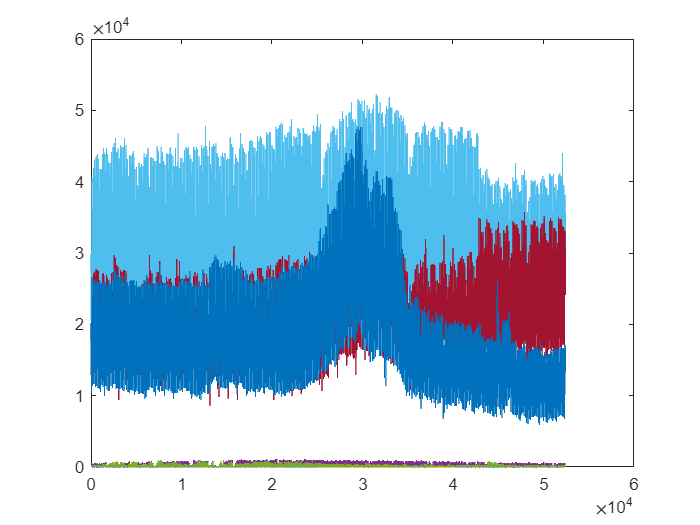

%% Visually (plot) all variables
plot(fileCSV)

### ***Answer 7***

%% Select the last column
lastCol = fileCSV(:,8)

lastCol = 1.0e+04 *

    2.0131
    1.9668
    1.8899
    1.8442
    1.8130
    1.7945
    1.7459
    1.7026
    1.6794
    1.6638


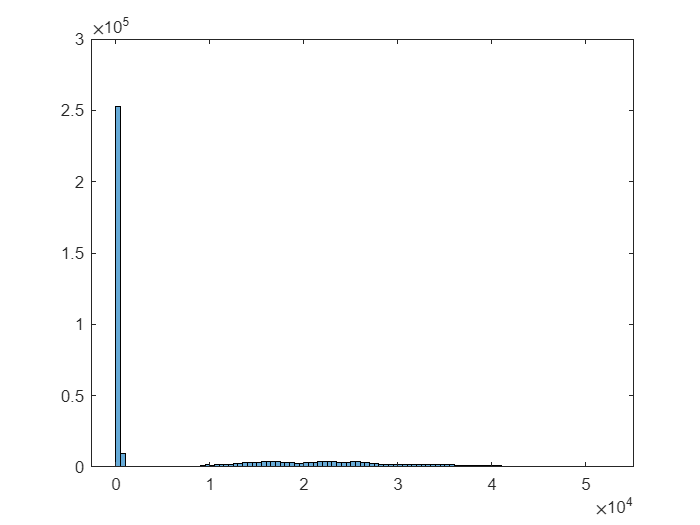

histogram(fileCSV)

%% k-means using the k value of 3
k_means_3 = kmeans(lastCol,3)

k_means_3 =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


%% %% k-means using the k value of 3
k_means_5 = kmeans(lastCol,5)

k_means_5 =      3
     3
     3
     3
     3
     3
     3
     4
     4
     4


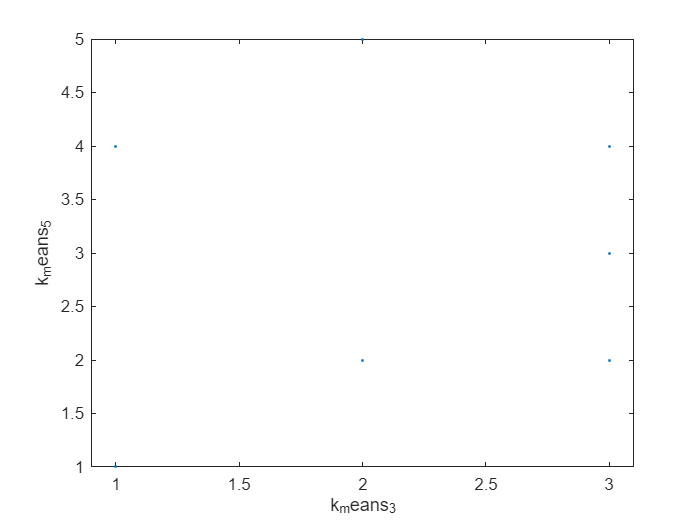

gscatter(k_means_3, k_means_5)